# 案例：二阶ODE求解

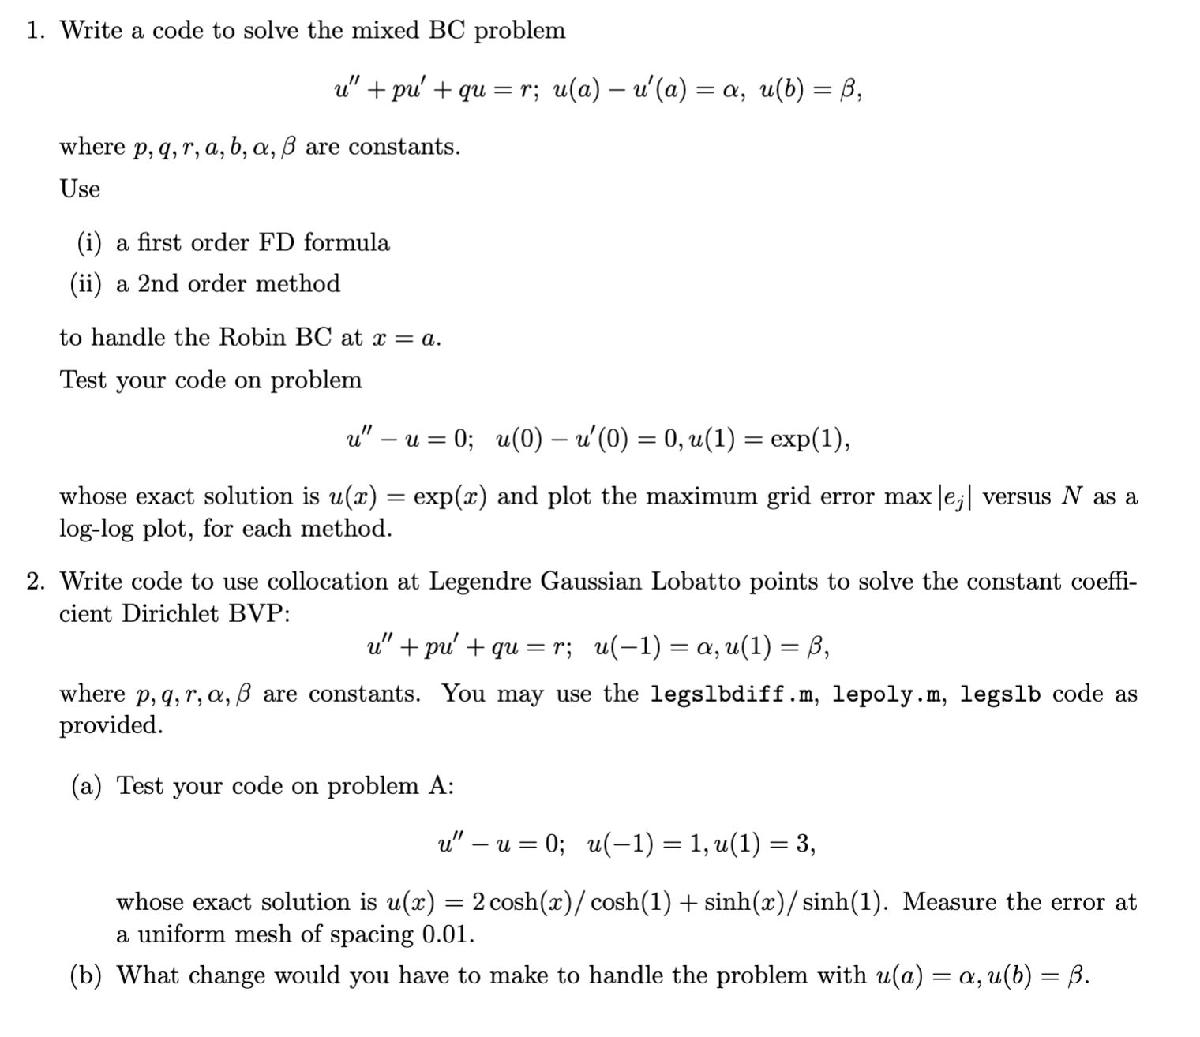

clear;clc;
% u' = (u(x+h) - u(x)) / h
% u'' = (u(x+h) + u(x-h) - 2*u(x)) / h^2
syms a
N = 100;
x = linspace(0, 1, N);
h = x(2) - x(1);
% 迭代计算初值
a1 = a;
a2 = (1 + h)*a1;
for i = 3:N
    an = (h^2+2)*a2 - a1;
    a1 = a2;
    a2 = an;
end
val_a = solve(an==exp(1), a);
val_a = double(val_a)

val_a = 1.0022

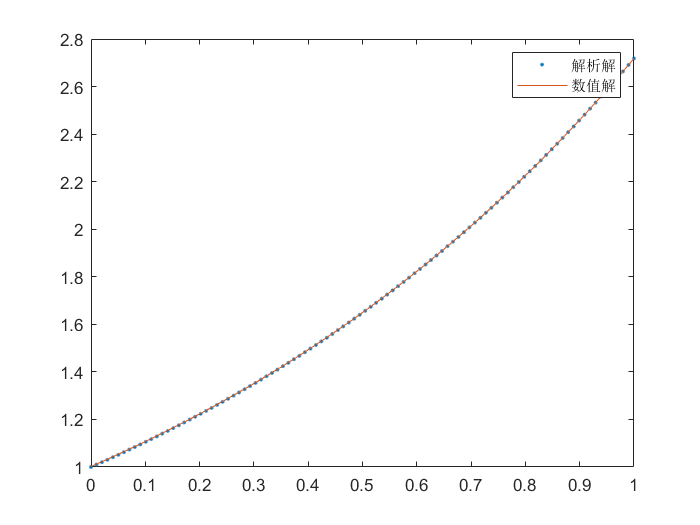


u = nan(N, 1);
u(1) = val_a;
u(2) = (1 + h)*u(1);
for i = 3:N
    u(i) = (h^2+2)*u(i-1) - u(i-2);
end
plot(x, exp(x), '.')
hold on
plot(x, u);
hold off
legend('解析解', '数值解');



N = 100;
x = linspace(-1, 1, N);
h = x(2) - x(1);
% 迭代计算第二个点的值
a1 = 1;
a2 = a;
for i = 3:N
    an = (h^2+2)*a2 - a1;
    a1 = a2;
    a2 = an;
end
val_a = solve(an==3, a);
val_a = double(val_a)

val_a = 0.9960

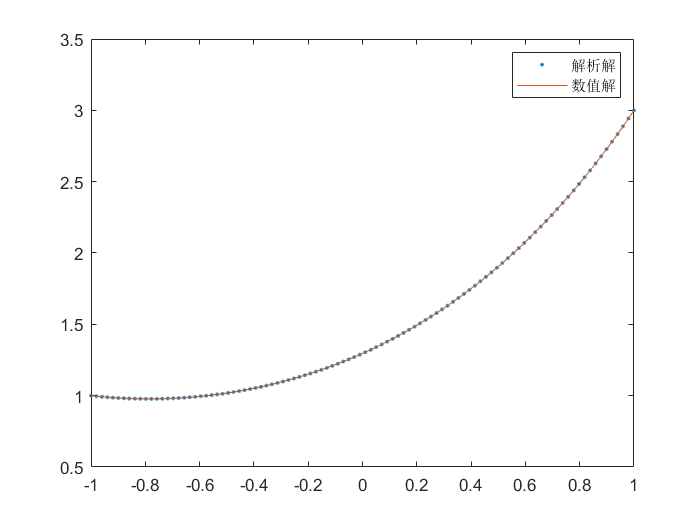


u = nan(N, 1);
u(1) = 1;
u(2) = val_a;
for i = 3:N
    u(i) = (h^2+2)*u(i-1) - u(i-2);
end
plot(x, 2*cosh(x)/cosh(1)+sinh(x)/sinh(1), '.')
hold on
plot(x, u);
hold off
legend('解析解', '数值解');